path = dir("G:\My Drive\1. Projects\PHYS-559 Graduate Laboratory (Spring 2023)\NMR Project\Final Paper Data\0.0306M\*.csv")

path = 39×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


sampleConcentration = '0.0306M'

sampleConcentration = '0.0306M'

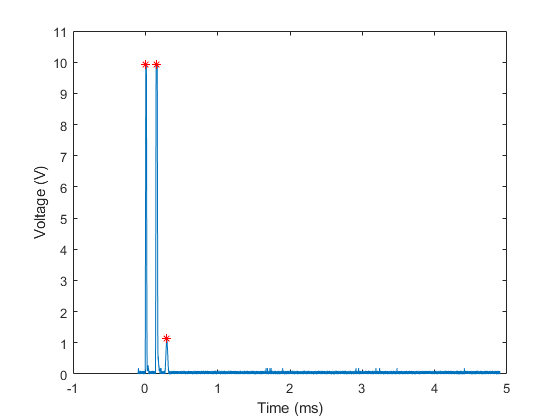

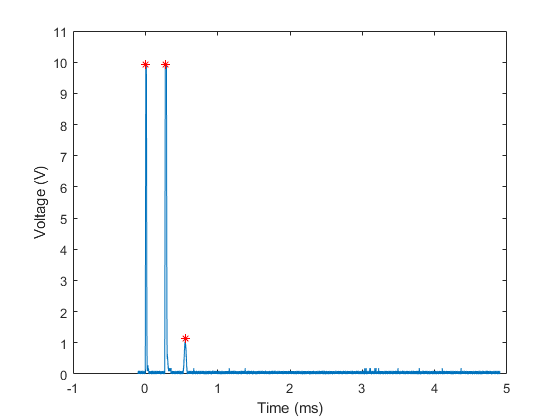

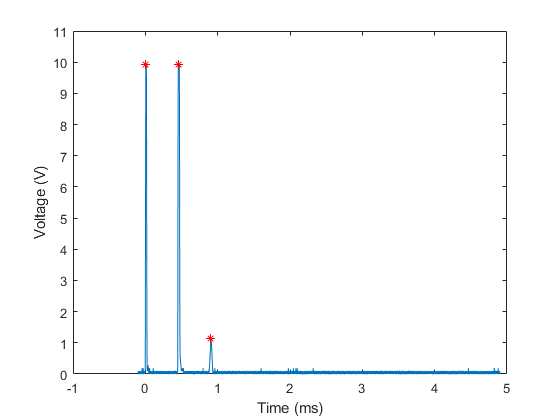

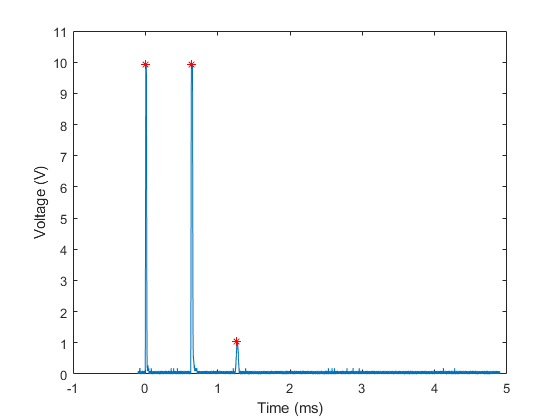

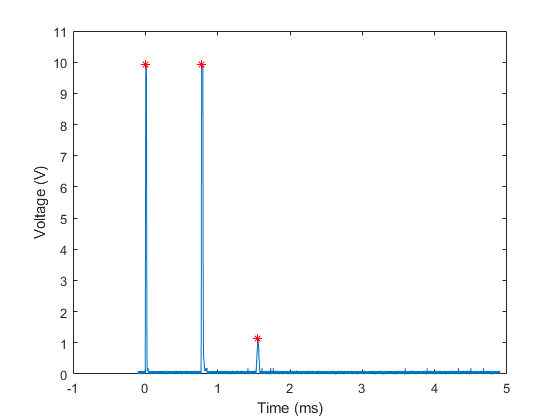

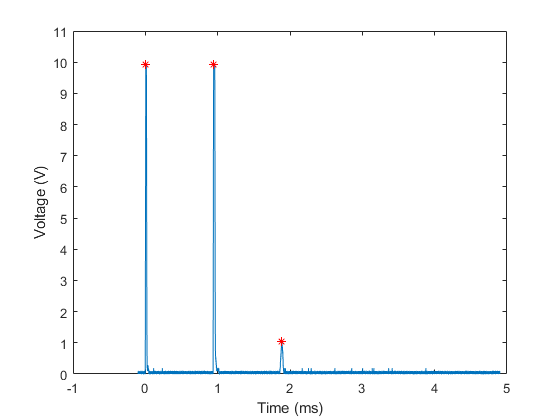

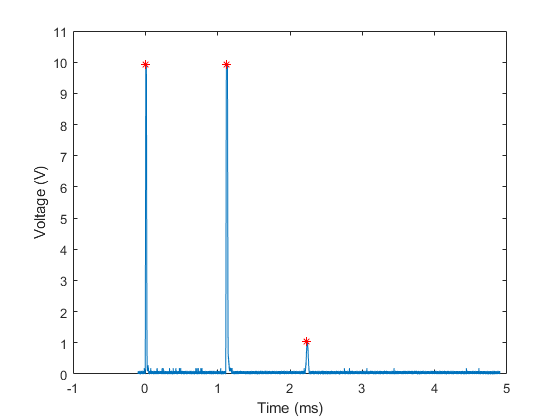

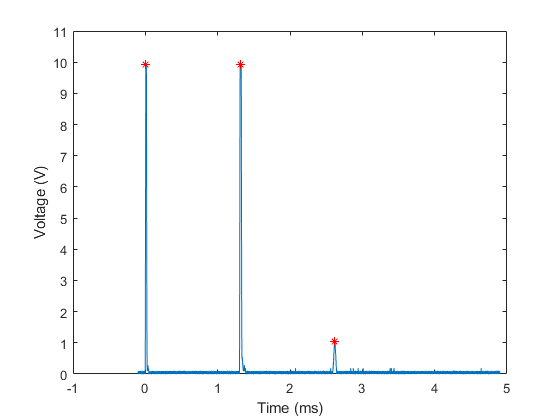

pulse_seperation =     0.1425    0.2696    0.4482    0.6298    0.7726    0.9377    1.1134    1.3036    1.4849    1.6489    1.8560    2.0431    2.1983    2.3503    2.4803    2.6296    2.7693    2.9476    3.1189    3.2810    3.4641    3.6152    3.7624    3.9141    4.0660    4.2079    4.4039    4.6129    4.7704    5.2326    5.7248    6.2132    6.6612    7.1440    7.7012    8.1718    8.7596    9.3794    9.6786


spinEchoAmp =     1.1230    1.1230    1.1230    1.0292    1.1230    1.0292    1.0292    1.0292    1.0292    1.0292    1.0292    1.0292    1.0292    1.0292    1.0292    1.0292    1.0292    1.0292    1.0292    1.0292    1.0292    1.0292    1.0292    1.0292    0.9357    1.0292    0.9357    0.9357    0.9357    0.9357    0.9357    0.8422    0.7486    0.7486    0.7486    0.6548    0.5613    0.5613    0.5613


[pulse_seperation, spinEchoAmp] = NMRdataAnalysis(path,sampleConcentration)

logSpinEchoAmp = log(spinEchoAmp)

logSpinEchoAmp =     0.1160    0.1160    0.1160    0.0287    0.1160    0.0287    0.0287    0.0287    0.0287    0.0287    0.0287    0.0287    0.0287    0.0287    0.0287    0.0287    0.0287    0.0287    0.0287    0.0287    0.0287    0.0287    0.0287    0.0287   -0.0665    0.0287   -0.0665   -0.0665   -0.0665   -0.0665   -0.0665   -0.1718   -0.2895   -0.2895   -0.2895   -0.4234   -0.5774   -0.5774   -0.5774


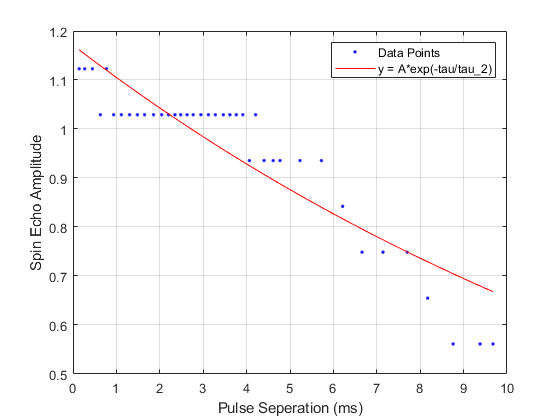

fitresult =      General model:
     fitresult(t) = A*exp(-t/t_2)
     Coefficients (with 95% confidence bounds):
       A =       1.171  (1.129, 1.214)
       t_2 =       17.24  (14.41, 20.06)

gof = struct with fields:
           sse: 0.1556
       rsquare: 0.8319
           dfe: 37
    adjrsquare: 0.8274
          rmse: 0.0648


[fitresult, gof] = exponentialFit(pulse_seperation, spinEchoAmp)

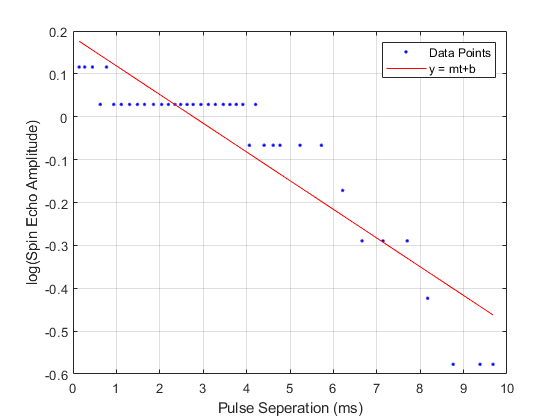

fitresult =      Linear model Poly1:
     fitresult(x) = p1*x + p2
       where x is normalized by mean 3.741 and std 2.63
     Coefficients (with 95% confidence bounds):
       p1 =     -0.1761  (-0.2012, -0.151)
       p2 =    -0.06481  (-0.08961, -0.04001)

gof = struct with fields:
           sse: 0.2162
       rsquare: 0.8450
           dfe: 37
    adjrsquare: 0.8408
          rmse: 0.0764


[fitresult, gof] = linearFit(pulse_seperation, logSpinEchoAmp)

function [fitresult, gof] = exponentialFit(pulse_seperation, spinEchoAmp)
%CREATEFIT(PULSE_SEPERATION,SPINECHOAMP)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      X Input : pulse_seperation
%      Y Output: spinEchoAmp
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 19-Feb-2023 22:36:59


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( pulse_seperation, spinEchoAmp );

% Set up fittype and options.
ft = fittype( 'A*exp(-t/t_2)', 'independent', 't', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.0461713906311539 0.0971317812358475];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'Exponential Fit' );
h = plot( fitresult, xData, yData );
legend( h, 'Data Points', 'y = A*exp(-tau/tau_2)', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Pulse Seperation (ms)', 'Interpreter', 'none' );
ylabel( 'Spin Echo Amplitude', 'Interpreter', 'none' );
grid on
end
function [fitresult, gof] = linearFit(pulse_seperation, logSpinEchoAmp)
%CREATEFIT1(PULSE_SEPERATION,LOGSPINECHOAMP)
%  Create a fit.
%
%  Data for 'Linear Fit' fit:
%      X Input : pulse_seperation
%      Y Output: logSpinEchoAmp
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 19-Feb-2023 22:39:47


%% Fit: 'Linear Fit'.
[xData, yData] = prepareCurveData( pulse_seperation, logSpinEchoAmp );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, 'Normalize', 'on' );

% Plot fit with data.
figure( 'Name', 'Linear Fit' );
h = plot( fitresult, xData, yData );
legend( h, 'Data Points', 'y = mt+b', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Pulse Seperation (ms)', 'Interpreter', 'none' );
ylabel( 'log(Spin Echo Amplitude)', 'Interpreter', 'none' );
grid on
end

